load("fullbridge.mat");
load("fullbridgeemi.mat");

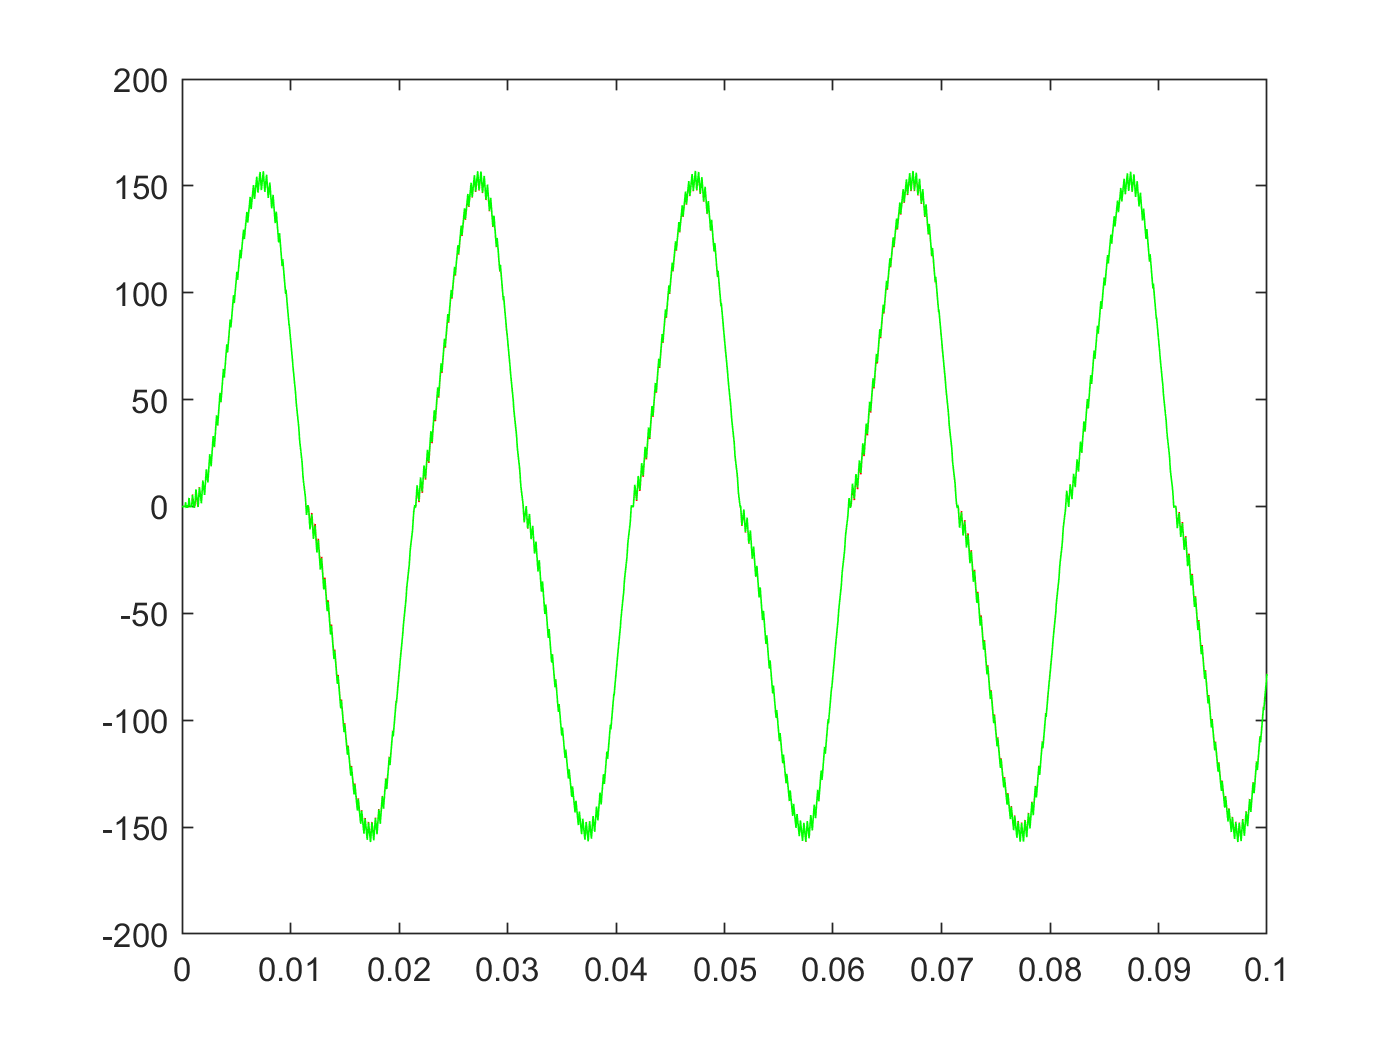

y1 = fullbridge.simout.Data;
y2 = fullbridgeemi.simout.Data;
x1 = fullbridge.tout;
x2 = fullbridgeemi.tout;
plot(x1,y1,'-r',x2,y2,'-g')

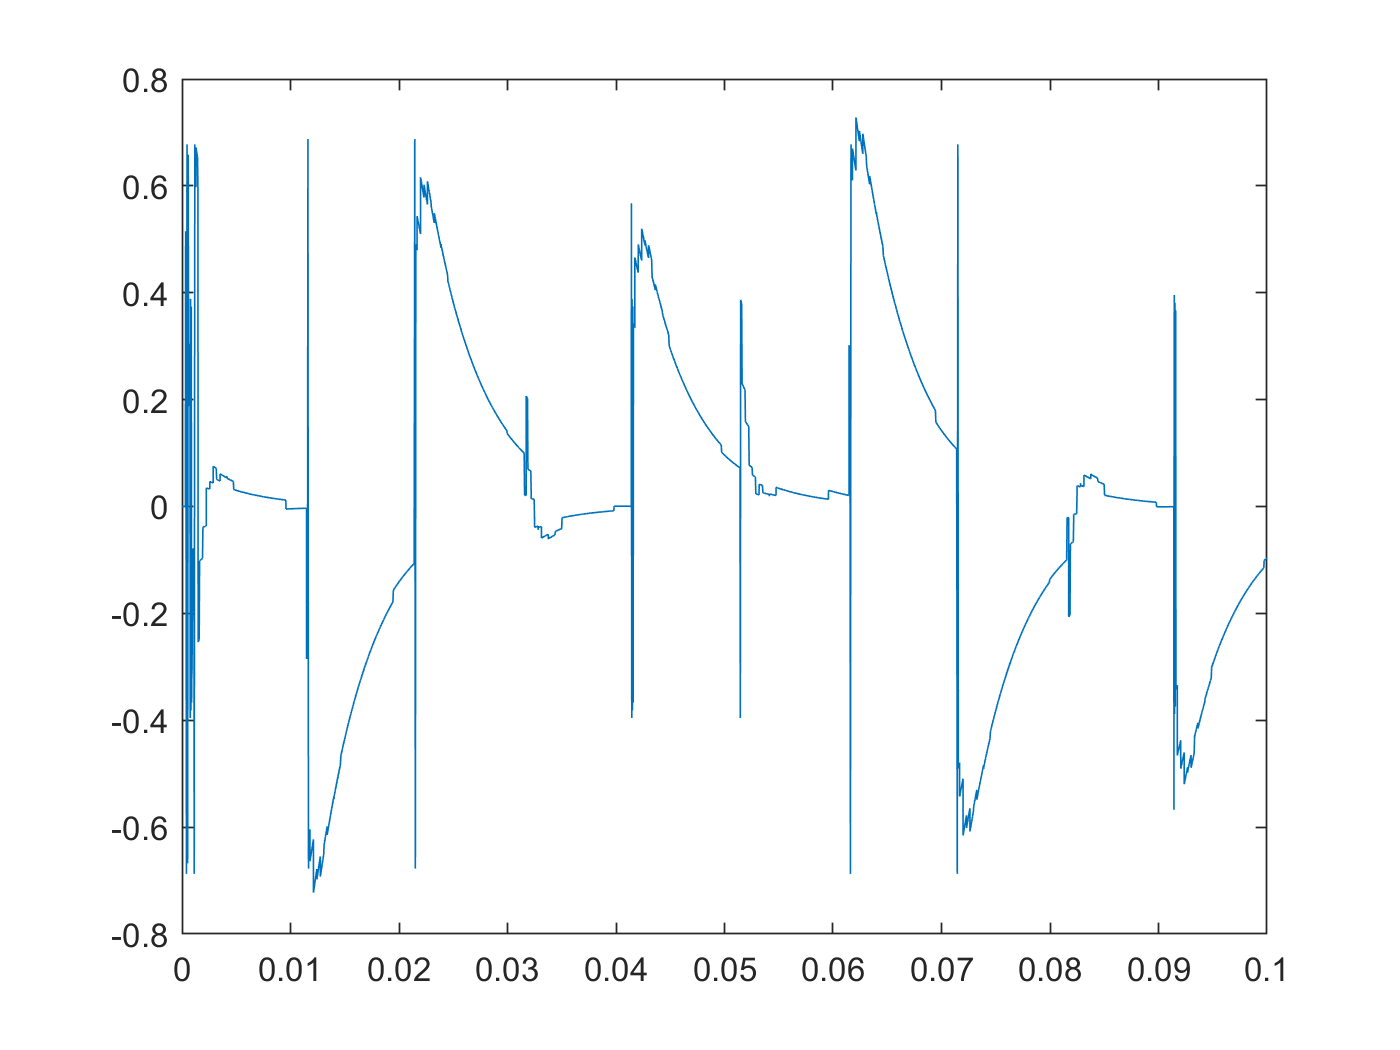

plot(x1,y2-y1)

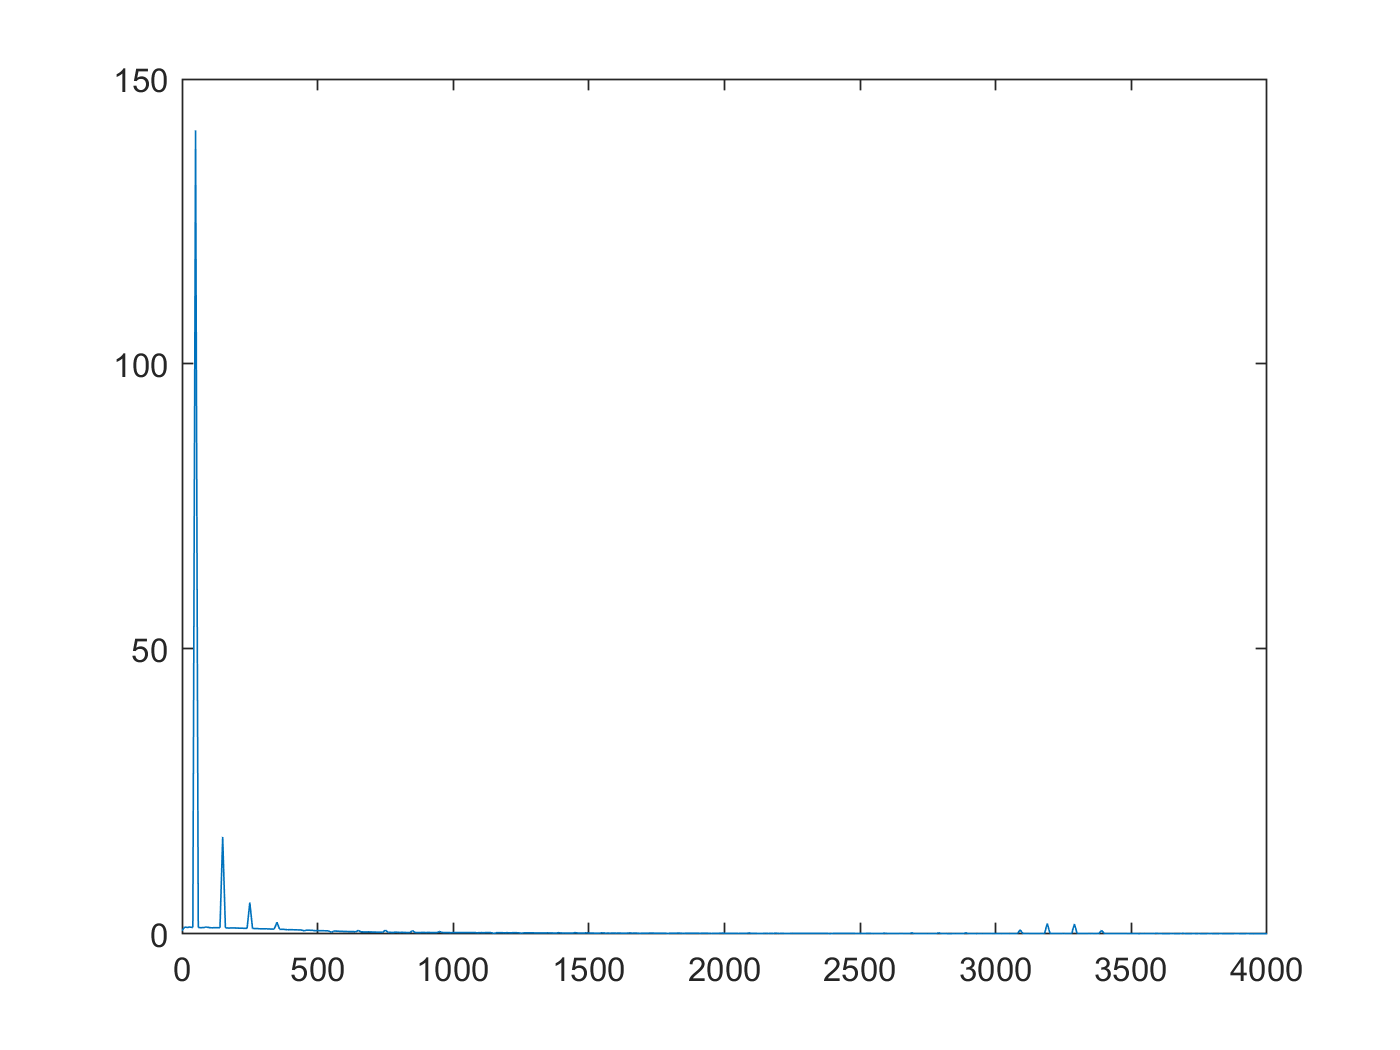

signalLength = 0.1;
frequency = 2e6;
s1 = fft(y1)/(signalLength*frequency);
s = 2 * abs( s1( 1:signalLength*frequency/500+1));
s(1) = s(1)/2;
fB = frequency/500;
f = fB * linspace(0, 1, signalLength*frequency/500+1);
plot(f,s)

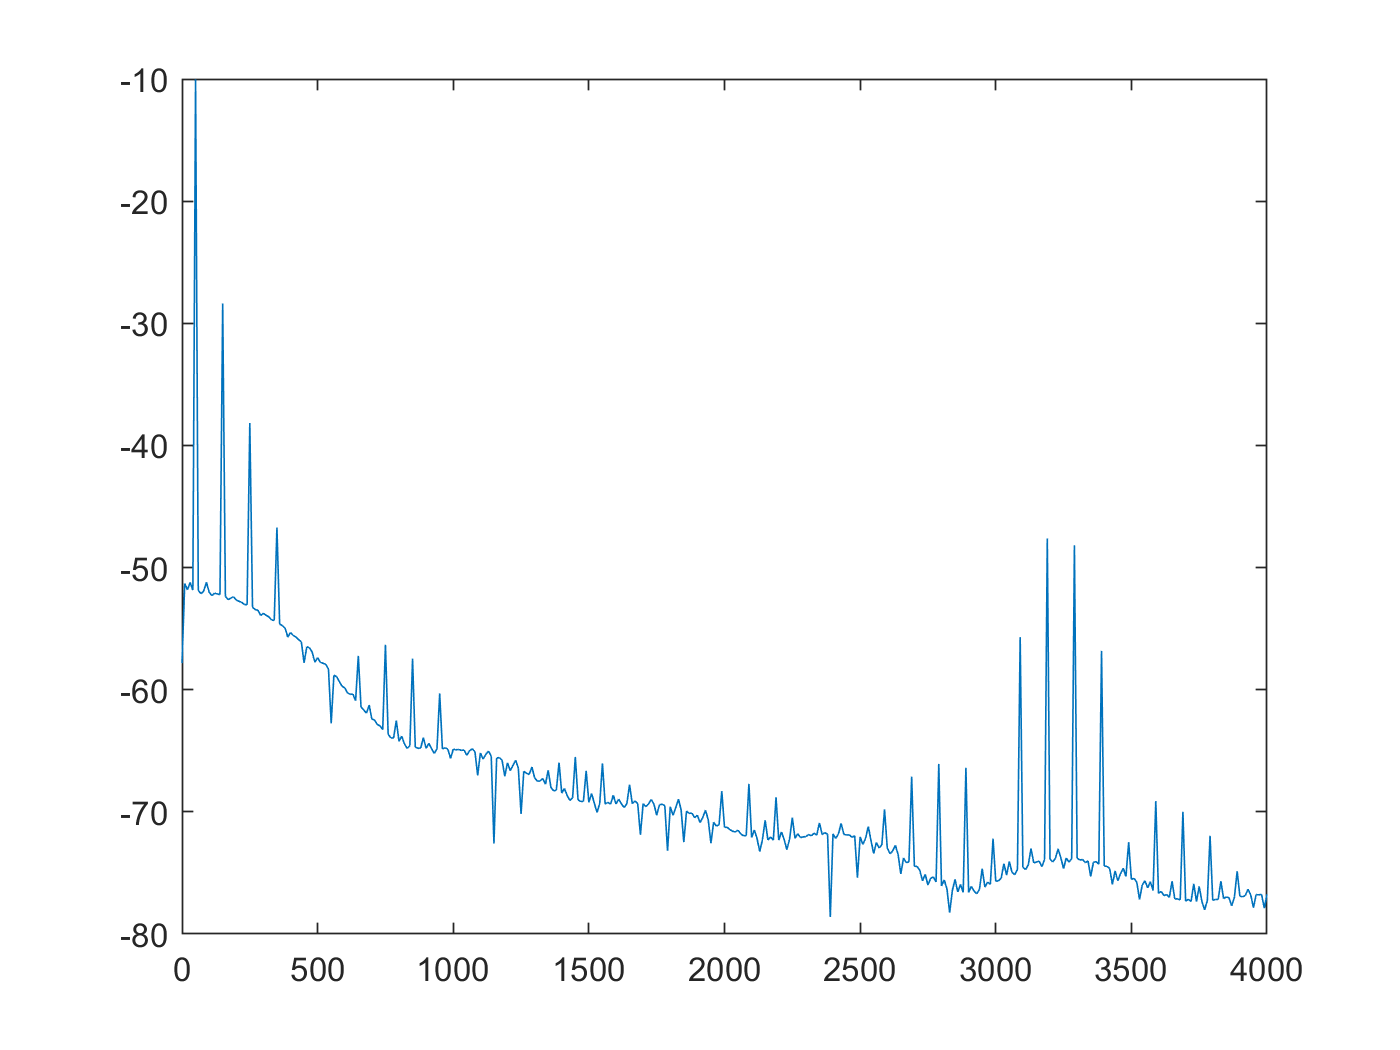

sdb = 20*log10(abs(s)) - 10*log10(signalLength*frequency);
plot(f,sdb)

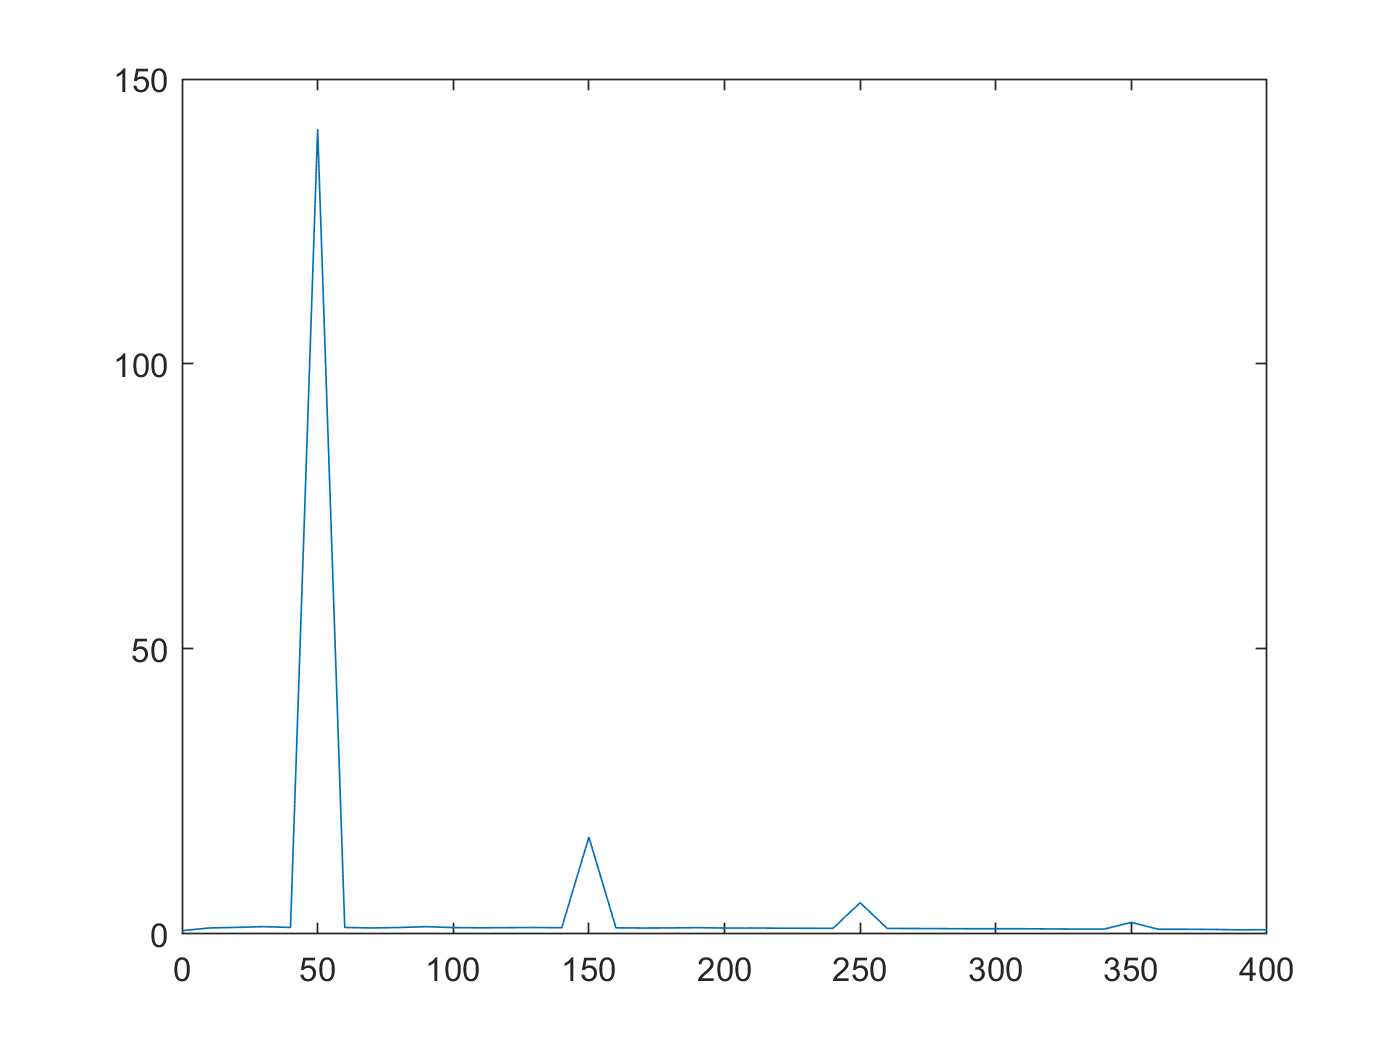

signalLength = 0.1;
frequency = 2e6;
s2 = fft(y2)/(signalLength*frequency);
s = 2 * abs( s2( 1:signalLength*frequency/5000+1));
s(1) = s(1)/2;
fB = frequency/5000;
f = fB * linspace(0, 1, signalLength*frequency/5000+1);
plot(f,s)

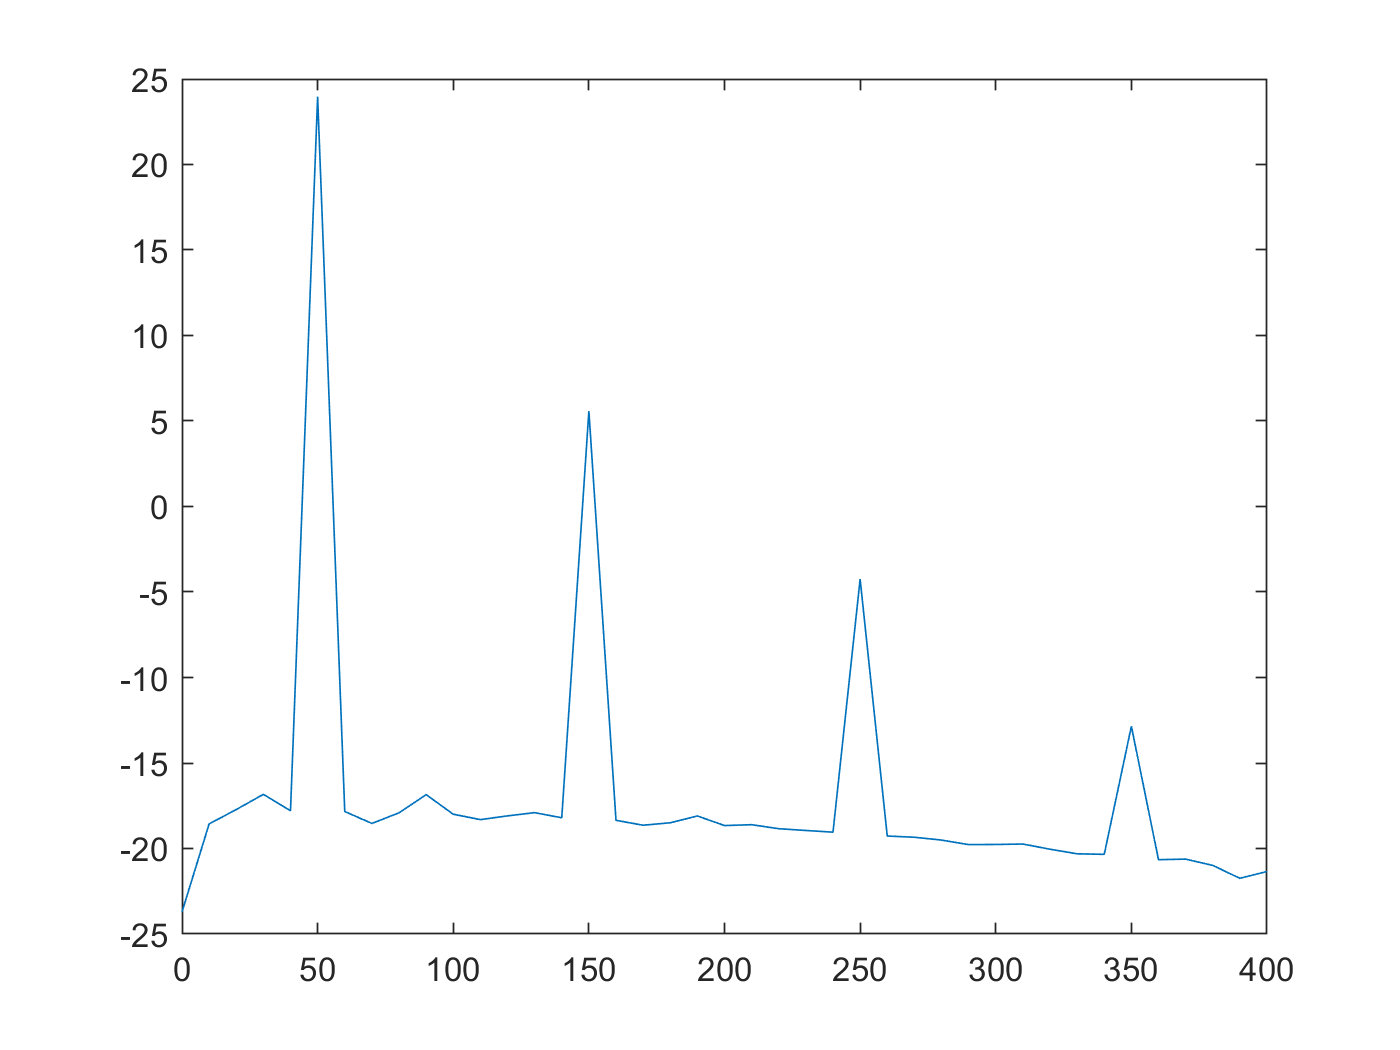

sdb = 20*log10(abs(s)) - 10*log10(signalLength*frequency/2500);
plot(f,sdb)